# Solve an Underdetermined System

## Task 1

Recall that an underdetermined system has more variables than equations. The following system of equations is underdetermined:

x+2z=1

2x+y+3z=5

This system has three variables x, y, and z, but only two equations. There are infinitely many solutions.

Task

Create the coefficient matrix `A` for the system.

The columns should represent the coefficients of x, y, then z.

A=[1 0 2; 2 1 3]

A =      1     0     2
     2     1     3


## Task 2

The system of equations is

x+2z=1

2x+y+3z=5

Task

Create the constant vector `b`.

b=[1 5]'

b =      1
     5


## Task 3

One known solution for the system is 

[5 1 −2]'

Task

Create a vector for this solution named `x1`.

x1=[5 1 -2]'

x1 =      5
     1
    -2


## Task 4 

Verify that `x1` is a solution by multiplying `A` and `x1`.

Save the output in a variable `Ax1`.

You may want to leave off the semicolon to display the output.

Ax1=A*x1

Ax1 =      1
     5


## Task 5

[5 1 −2]' is just one solution for this system. Using the backslash operator (`\`) in MATLAB will always return the solution with the greatest number of zero elements.

Task

Find a solution to the system of equations using the backslash operator. Name the output `x2`.

x2=A\b

x2 =          0
    3.5000
    0.5000


## Task 6

Verify that `x2` is also a solution for this system of equations by multiplying `A` times `x2`.

Save the output in a variable `Ax2`.

You may want to leave off the semicolon to display the output.

Ax2=A*x2

Ax2 =      1
     5


## Further Practice

Both `x1` and `x2` are solutions to the system of equations

x+2z=1

2x+y+3z=5

Even though there are infinitely many solutions, the backlash operator will always return the vector [0 3.5 0.5]'.

You can visualize the solutions for this system. Each equation is a plane  in three-dimensional space, and the solutions are on the line where the  two planes intersect.

The following code plots the two planes, and the solutions you found in this activity.

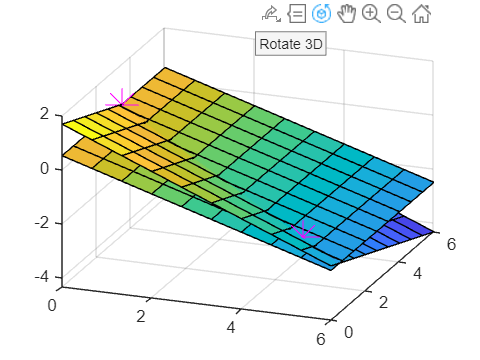

plotRange = linspace(0,6,10);
[X,Y] = meshgrid(plotRange);
Z1 = 0.5*(1-X);
Z2 = (1/3)*(5-Y-2*X);
surf(X,Y,Z1)
hold on
surf(X,Y,Z2)
plot3(5,1,-2,"m*","MarkerSize",20)
plot3(0,3.5,0.5,"m*","MarkerSize",20)
hold off